concentration = [0.115, 0.0306, 0.03082, 0.1224, 0.1498, 0.3059]

concentration =     0.1150    0.0306    0.0308    0.1224    0.1498    0.3059


tau2 = 1./[5.062,17.24,9.375,4.342,2.216,1.138]

tau2 =     0.1976    0.0580    0.1067    0.2303    0.4513    0.8787


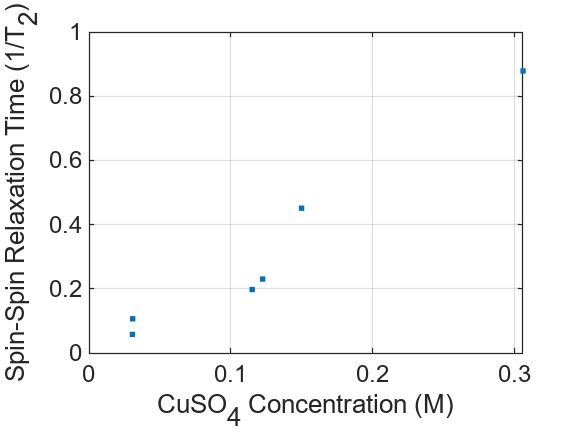

figure;
plot(concentration,tau2,'.')
grid on
xlabel('CuSO_4 Concentration (M)')
ylabel('Spin-Spin Relaxation Time (1/T_2)')

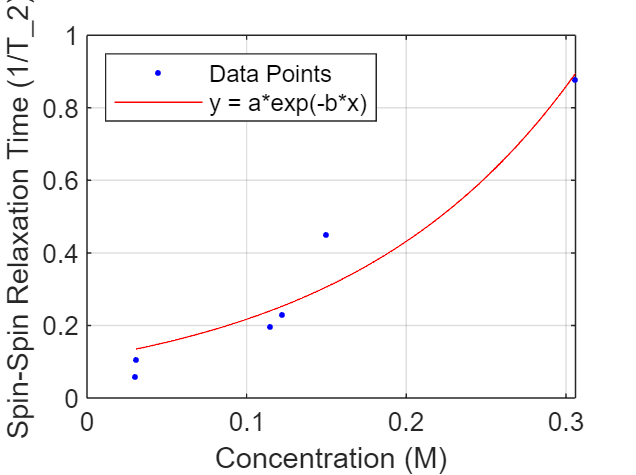

fitresult =      General model:
     fitresult(x) = a*exp(-b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1092  (0.02365, 0.1947)
       b =      -6.876  (-9.74, -4.013)

gof = struct with fields:
           sse: 0.0305
       rsquare: 0.9347
           dfe: 4
    adjrsquare: 0.9183
          rmse: 0.0873


[fitresult, gof] = createFit(concentration, tau2)

function [fitresult, gof] = createFit(concentration, tau2)
%CREATEFIT(CONCENTRATION,TAU2)
%  Create a fit.
%
%  Data for 'y = a*exp(-b*x)' fit:
%      X Input : concentration
%      Y Output: tau2
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 23:53:06


%% Fit: 'y = a*exp(-b*x)'.
[xData, yData] = prepareCurveData( concentration, tau2 );

% Set up fittype and options.
ft = fittype( 'a*exp(-b*x)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.118997681558377 0.498364051982143];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'y = a*exp(-b*x)' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = a*exp(-b*x)', 'Location', 'NorthWest', 'Interpreter', 'none' );
% Label axes
xlabel( 'Concentration (M)', 'Interpreter', 'none' );
ylabel( 'Spin-Spin Relaxation Time (1/T_2)', 'Interpreter', 'none' );
grid on
end